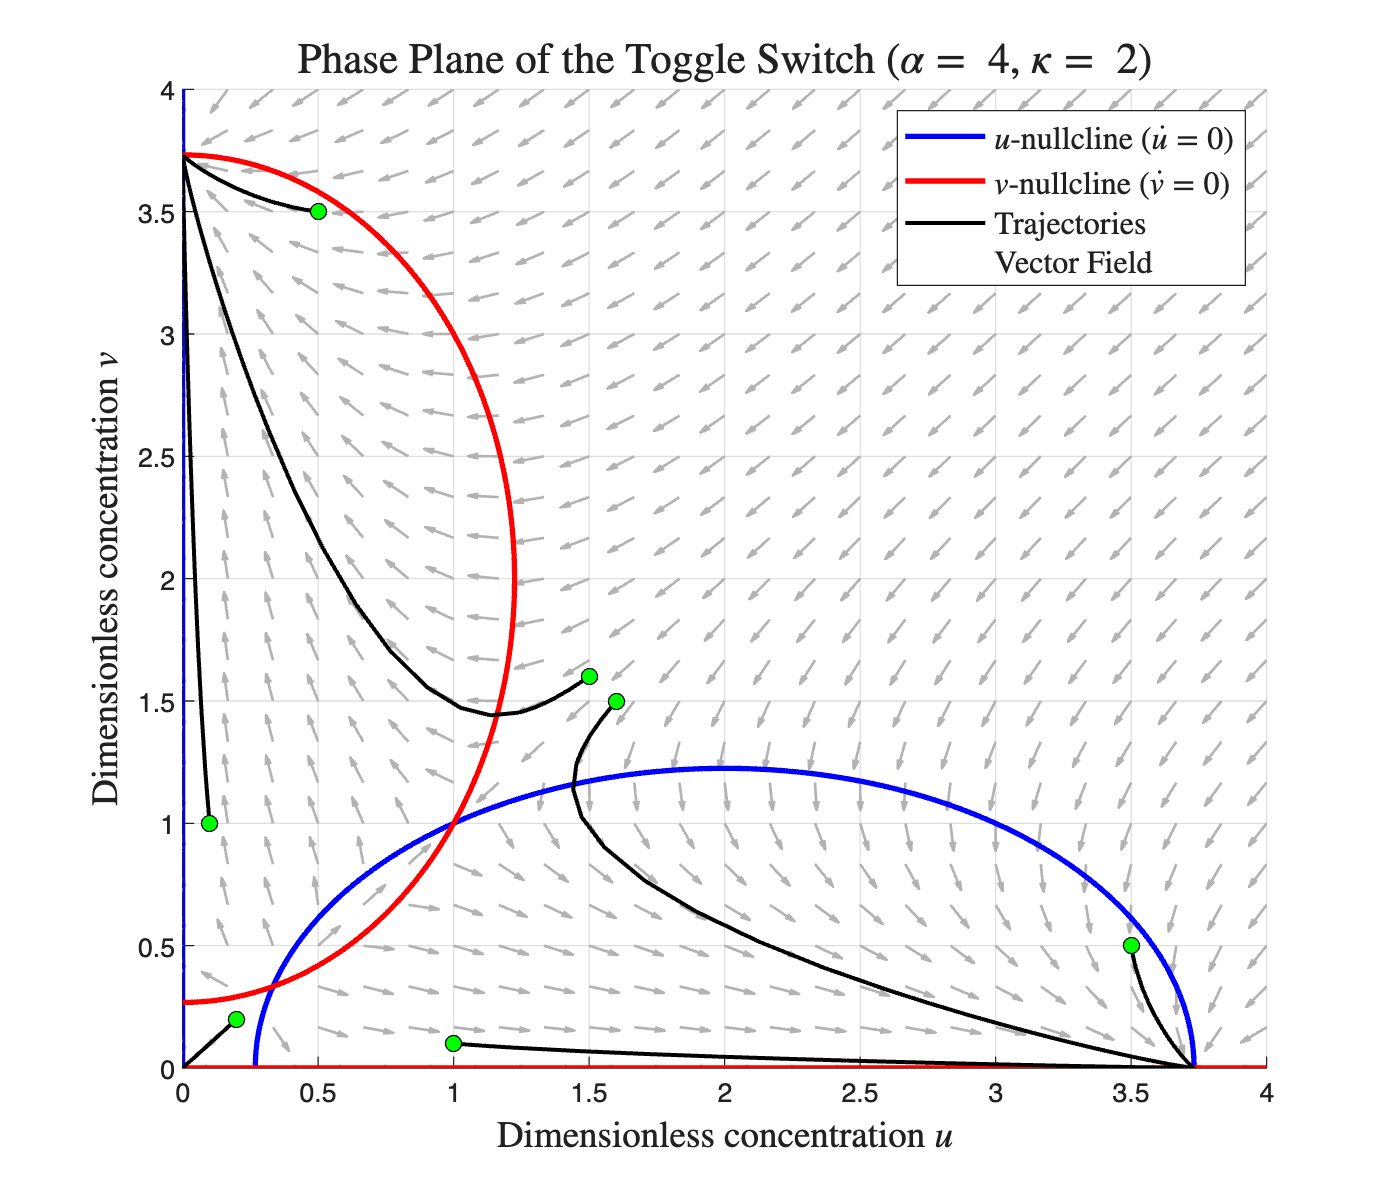

% Phase Plane Analysis for the Genetic Toggle Switch
% System: 
% du/dt = alpha * u^2 / (1 + u^2 + kappa * v^2) - u
% dv/dt = alpha * v^2 / (1 + kappa * u^2 + v^2) - v

clear; clc; close all;

% 1. Define dimensionless parameters (Bistable regime)
alpha = 4.0;
kappa = 2.0;

% 2. Setup the grid for the vector field
u_max = 4;
v_max = 4;
[u_grid, v_grid] = meshgrid(linspace(0, u_max, 25), linspace(0, v_max, 25));

% Calculate the derivatives on the grid
du = alpha * (u_grid.^2) ./ (1 + u_grid.^2 + kappa * v_grid.^2) - u_grid;
dv = alpha * (v_grid.^2) ./ (1 + kappa * u_grid.^2 + v_grid.^2) - v_grid;

% Normalize the arrows for a cleaner quiver plot
L = sqrt(du.^2 + dv.^2);
% Add small eps to avoid division by zero at the origin
du_norm = du ./ (L + eps); 
dv_norm = dv ./ (L + eps);

% Create figure
figure('Position', [100, 100, 700, 600]);
hold on;

% 3. Plot the vector field (flow directions)
quiver(u_grid, v_grid, du_norm, dv_norm, 0.5, 'color', [0.7 0.7 0.7], 'LineWidth', 1);

% 4. Plot Nullclines using implicit contour plotting
% Create a higher resolution grid for smooth nullcline curves
[U_hr, V_hr] = meshgrid(linspace(0, u_max, 400), linspace(0, v_max, 400));
dU_hr = alpha * (U_hr.^2) ./ (1 + U_hr.^2 + kappa * V_hr.^2) - U_hr;
dV_hr = alpha * (V_hr.^2) ./ (1 + kappa * U_hr.^2 + V_hr.^2) - V_hr;

% u-nullclines (blue): where du/dt = 0
% Note: the u-axis (v=0) is also a v-nullcline, and v-axis (u=0) is a u-nullcline
contour(U_hr, V_hr, dU_hr, [0 0], 'b', 'LineWidth', 2); 
plot([0, 0], [0, v_max], 'b', 'LineWidth', 2); % u=0 trivial nullcline

% v-nullclines (red): where dv/dt = 0
contour(U_hr, V_hr, dV_hr, [0 0], 'r', 'LineWidth', 2);
plot([0, u_max], [0, 0], 'r', 'LineWidth', 2); % v=0 trivial nullcline

% 5. Plot representative trajectories
% Define the ODE function
ode_func = @(t, y) [alpha * y(1)^2 / (1 + y(1)^2 + kappa * y(2)^2) - y(1); ...
                    alpha * y(2)^2 / (1 + kappa * y(1)^2 + y(2)^2) - y(2)];

% List of initial conditions [u0, v0] to show different basins of attraction
y0_list = [0.1, 1.0; 
           1.0, 0.1; 
           1.5, 1.6; 
           1.6, 1.5; 
           3.5, 0.5; 
           0.5, 3.5;
           0.2, 0.2]; % Near origin

% Solve and plot each trajectory
for i = 1:size(y0_list, 1)
    [t, Y] = ode45(ode_func, [0, 20], y0_list(i, :));
    plot(Y(:,1), Y(:,2), 'k', 'LineWidth', 1.5);
    % Mark the starting point with a green dot
    plot(Y(1,1), Y(1,2), 'o', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'g', 'MarkerSize', 6);
end

% 6. Formatting the plot
xlabel('Dimensionless concentration $u$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('Dimensionless concentration $v$', 'Interpreter', 'latex', 'FontSize', 14);
title(['Phase Plane of the Toggle Switch ($\alpha = $ ', num2str(alpha), ...
       ', $\kappa = $ ', num2str(kappa), ')'], 'Interpreter', 'latex', 'FontSize', 16);
   
% Create dummy plots for the legend to look clean
h1 = plot(nan, nan, 'b', 'LineWidth', 2);
h2 = plot(nan, nan, 'r', 'LineWidth', 2);
h3 = plot(nan, nan, 'k', 'LineWidth', 1.5);
h4 = quiver(nan,nan,nan,nan, 'color', [0.7 0.7 0.7]);
legend([h1, h2, h3, h4], {'$u$-nullcline ($\dot{u}=0$)', '$v$-nullcline ($\dot{v}=0$)', ...
       'Trajectories', 'Vector Field'}, 'Interpreter', 'latex', 'FontSize', 12, 'Location', 'northeast');

axis([0 u_max 0 v_max]);
grid on;
hold off;

exportgraphics(gcf, 'Bifurcation_Diagram.png', 'Resolution', 300);